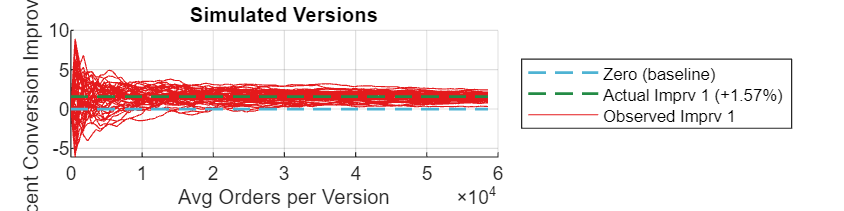

%% Initialization and Setup
clear; 
reset(figure);
start_time = datetime;

% Parameters
base_conv = 50;
factor = 10;
aa_test = 0; % force all version b:end to match a.
versions = 2;
new_vis_per_iter = 1000;
set_iter = 100;
num_sims = 50;
slo_reveal_first_sims = 1;
slo_reveal_repeat_sims = 1;

% Generate conversion rates
Conv_rates = (base_conv + rand(1,versions) * factor)/100; 
if aa_test == 1
    Conv_rates(2:versions) = Conv_rates(1);
end

%% Simulation
rng('shuffle');
Obs_conv_rates = zeros(set_iter+1, versions*num_sims);  
Obs_conv_imprvs = zeros(set_iter+1, (versions-1)*num_sims);  
Orders = zeros(set_iter+1, versions*num_sims);
Visitor_counts = zeros(set_iter+1, 1);
True_conv_imprvs = (((Conv_rates(end,2:versions) - Conv_rates(end,1)) / Conv_rates(end,1)) + 1 - 1) * 100;

for iter = 1:set_iter
    Visitors = rand(new_vis_per_iter, versions*num_sims);
    Orders(iter+1,:) = Orders(iter,:) + sum(Visitors < repmat(Conv_rates,1,num_sims), 1);
    Visitor_counts(iter+1,:) = Visitor_counts(iter) + new_vis_per_iter;
    Obs_conv_rates(iter+1,:) = Orders(iter+1,:) ./ Visitor_counts(iter+1);
    
    % Separate control from experimental visitors
    G = reshape(1:versions*num_sims, versions, num_sims).';
    Ve = reshape(G(:,2:end).', 1, []); 
    Vc = repelem(G(:,1).', versions-1);
    
    Obs_conv_imprvs(iter+1,:) = (((Obs_conv_rates(iter+1, Ve) - Obs_conv_rates(iter+1, Vc)) ./ Obs_conv_rates(iter+1, Vc)) + 1 - 1) * 100;
end

%% Plotting
opg = round(sum(Orders(end,:), 2) / versions / num_sims, 0);
opg_note = sprintf('Appx Orders per Group: %g\n', round(opg, -2));
vps_note = sprintf('Visitors generated simulations: %g million', versions * new_vis_per_iter * set_iter * num_sims / 1e6);

% Define colors
act_imp_col = brewermap(4, 'Greens');
act_imp_col = act_imp_col(end,:);
zero_imp_col = brewermap(2, 'GnBu');
zero_imp_col = zero_imp_col(end,:);
sim_imp_col = brewermap(1, 'Set1');
sim_imp_col = sim_imp_col(end,:);

% Plot
clf;
f = figure;
f.Position = [1 2 2400 600];
linewid = 1.2;
hold on;



True_conv_imprv_plot = zeros(2,versions);
True_conv_imprv_plot(2,1)=(sum(Orders(end,:),2)/versions)/num_sims;
True_conv_imprv_plot(:,2:versions)=[True_conv_imprvs;True_conv_imprvs];
plot(True_conv_imprv_plot(:,1),zeros(2,1), "--", "Color", zero_imp_col, "LineWidth", linewid);

if  aa_test == 1
    plot(True_conv_imprv_plot(:,1),True_conv_imprv_plot(:,2), "--", "Color",act_imp_col, "LineWidth", linewid ); % only plot one green line in aa test mode
else
    plot(True_conv_imprv_plot(:,1),True_conv_imprv_plot(:,2:versions), "--", "Color",act_imp_col, "LineWidth", linewid); 
end
    
All_sims = [(sum(Orders,2)/versions)/num_sims,Obs_conv_imprvs];

    if slo_reveal_first_sims == 1
        for slo_iter = 1:set_iter
        plot(All_sims(slo_iter:slo_iter+1,1),All_sims(slo_iter:slo_iter+1,2:versions), "-", "Color",sim_imp_col);
        pause(0.001)
        end
    else
        plot((sum(Orders,2)/versions)/num_sims,Obs_conv_imprvs(:,versions), "-", "Color",sim_imp_col);
    end

    zero_label = {'Zero (baseline)'};
    labels = zero_label;
    ver_nums = string(1:versions-1);
    ver_actual_impvs = string(zeros(1,versions-1));

    if aa_test == 1
        labels_act = strcat("True Improvement (",ver_actual_impvs,")");
        str = sprintf("%+3.2f%%", True_conv_imprvs(1,1));
        str2 = "Simulations of observed improvement";
        labels = horzcat(zero_label,str,str2);
    
    elseif versions < 25

        for iter = 1:versions-1
        str = sprintf("%+3.2f%%", True_conv_imprvs(1,iter));
        ver_actual_impvs(iter) = str;
        end

        labels_obs = strcat("Observed Imprv ",ver_nums);
        labels_act = strcat("Actual Imprv ",ver_nums, " (",ver_actual_impvs,")");
        labels = horzcat(zero_label,labels_act,labels_obs);
    end       
    legend(labels,'location','eastoutside','AutoUpdate','off');
    xlabel('Avg Orders per Version');
    ylabel('Percent Conversion Improvement');
    title("Simulated Versions")

if num_sims > 0
    
    if slo_reveal_repeat_sims == 1
        for slo_iter = 1:set_iter
        plot(All_sims(slo_iter:slo_iter+1,1),All_sims(slo_iter:slo_iter+1,2:end), "-", "Color",sim_imp_col);
        pause(0.001)
        end
    else
        plot(All_sims(:,1),All_sims(:,2:end), "-", "Color",sim_imp_col);
    end
end

% repeat plotting the baseline and actual improvement lines for visiblity. 
% Must keep redundant originals in code so legend can be correctly defined.
% Have to add to legend in same order of plotting, since we ignore the repeat_sim lines, we must plot twice.

    if  aa_test == 1
        plot(True_conv_imprv_plot(:,1),True_conv_imprv_plot(:,2), "--", "Color",act_imp_col, "LineWidth",linewid); % only plot one green line in aa test mode
    else
        plot(True_conv_imprv_plot(:,1),True_conv_imprv_plot(:,2:versions), "--", "Color",act_imp_col, "LineWidth",linewid); 
    end
    
    plot(True_conv_imprv_plot(:,1),zeros(2,1), "--", "Color",zero_imp_col, "LineWidth",linewid);
    grid on
hold off


% xlim([opg - opg*.01 opg + opg*.01])
% ylim([-3 3])

%% Final Outputs
end_time = datetime;
time_elapsed = seconds(diff(datetime([start_time; end_time])));
fprintf('Time to generate simulations: %.1fs\n', time_elapsed);

Time to generate simulations: 13.8s


fprintf(opg_note);

Appx Orders per Group: 58600


fprintf(vps_note);

Visitors generated simulations: 10 million